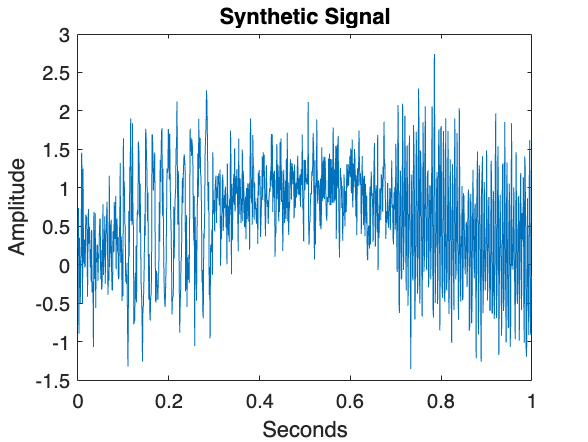

Fs = 1e3;
t = 0:1/Fs:1-1/Fs;
comp1 = cos(2*pi*200*t).*(t>0.7);
comp2 = cos(2*pi*60*t).*(t>=0.1 & t<0.3);
trend = sin(2*pi*1/2*t);
rng default
wgnNoise = 0.4*randn(size(t));
x = comp1+comp2+trend+wgnNoise;
plot(t,x)
xlabel('Seconds')
ylabel('Amplitude')
title('Synthetic Signal')

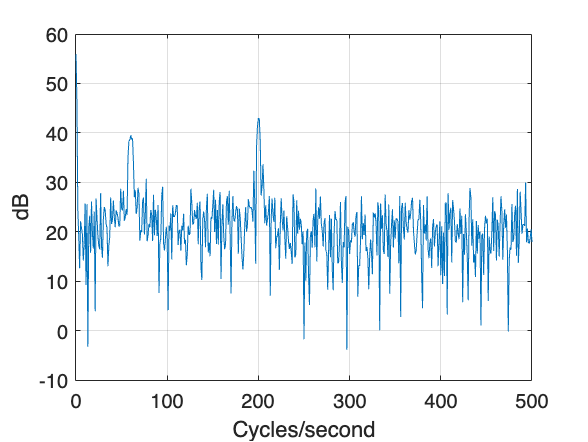

xdft = fft(x);
N = numel(x);
xdft = xdft(1:numel(xdft)/2+1);
freq = 0:Fs/N:Fs/2;
plot(freq,20*log10(abs(xdft)))
xlabel('Cycles/second')
ylabel('dB')
grid on;

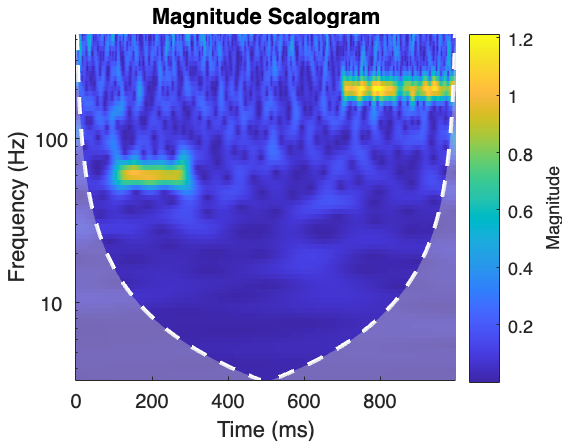

cwt(x,Fs);

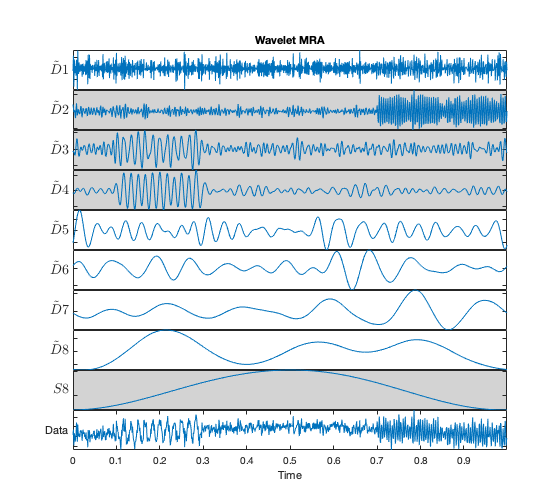

mra = modwtmra(modwt(x,8));
helperMRAPlot(x,mra,t,'wavelet','Wavelet MRA',[2 3 4 9])